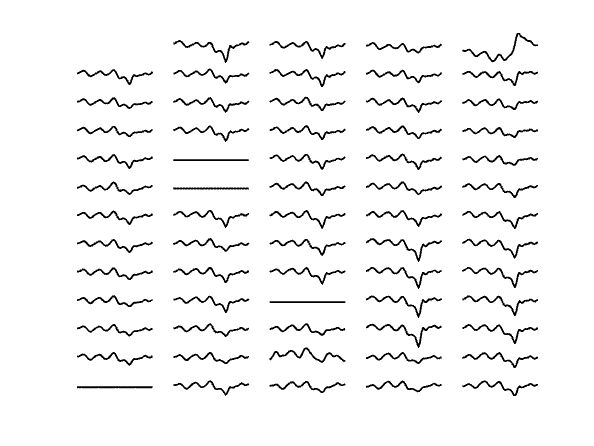

figure;
muap=muaparray{10};
plotArrayPotential(muap,1,1);


precentage=0.7;

k=1;
[i_end,j_end]=size(muap);
empty_loc=zeros(i_end,j_end);
for i=1:1:i_end
    for j=1:1:j_end
        if isempty(muap{i,j})
            empty_loc(i,j)=1;
            continue
        end
        matrix_muap(k,:)=muap{i,j};
        k=k+1;
    end
end
matrix_zeromean=matrix_muap-mean(matrix_muap,1);
sigma=cov(matrix_zeromean');
[u,s,v]=svd(sigma);
eigenvalue=diag(s);

for vec_idx=1:length(eigenvalue)
eigenvalue=diag(s);
   if (sum(eigenvalue(1:vec_idx))/sum(eigenvalue)>=precentage)
       break
   end
end


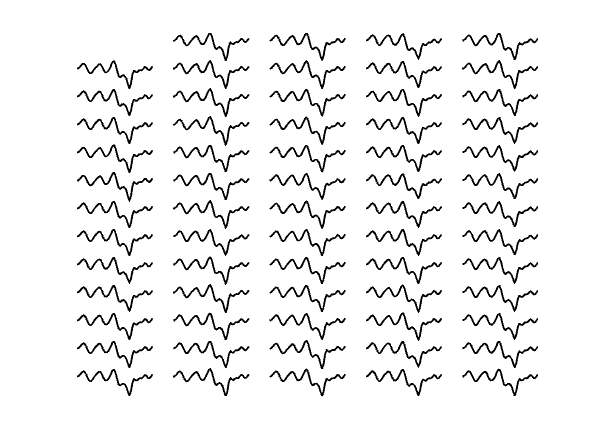


eigenvectors=u(:,6);%文章中是取前四
matrix_recon=matrix_zeromean'*eigenvectors*eigenvectors'+mean(matrix_muap,1)';
matrix_recon=matrix_recon';
figure;k=1;
for i=1:1:13
    for j=1:1:5
        if empty_loc(i,j)==1;
            continue
        end
        muap_recon{i,j}=matrix_recon(k,:);
        k=k+1;
    end
end
plotArrayPotential(muap_recon,1,1);